file = audioread("hey04_8bit.wav")*128 + 128;
%file = audioread("nuit04_8bit.wav")*128;
%file = audioread("speech.wav")*128;



symbol_count = zeros(max(file), 1);

%Random distribution
p = random_distribution(file)

p =          0
         0
         0
         0
         0
         0
    0.0000
         0
    0.0000
    0.0000



%Entropy
Hx = entropy(p)

Hx = 7.1638

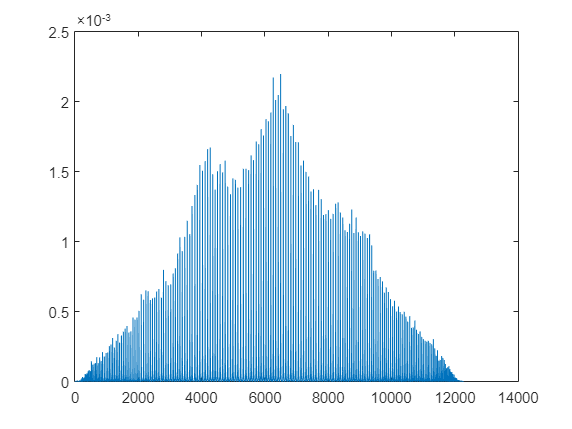


%parentropi
pair_count = zeros(256);

    for i = 1:size(file, 1)-1
    index = file(i);
    index2 = file(i + 1);
    pair_count(index, index2) = pair_count(index, index2)+1;
    end

    p_pairs = pair_count/(size(file, 1) - 1);
    p_pairs = p_pairs(find(p_pairs));
    plot(p_pairs);



    H2 = entropy(p_pairs)

H2 = 11.4363


%Betingad 
  H_cond =  H2 - Hx

H_cond = 4.2725

clear

%Photo = imread("baboon.png");
%Photo = imread("woodgrain.png");
Photo = imread("boat.png");

Photo = double(Photo)+1;

p_single = distribution2d(Photo);
H_single = entropy(p_single)

H_single = 7.1238




%parentropi horisnontell
p_hori = distribution2d_pair(Photo,[0 1]);
H_horizontal_pair = entropy(p_hori)

H_horizontal_pair = 12.0285


%parentropi vertikal
p_vert = distribution2d_pair(Photo,[1 0])

p_vert =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0

H_vertical_pair = entropy(p_vert)

H_vertical_pair = 11.7924


%Betingad horisontell
H_hori_cond = H_horizontal_pair - H_single

H_hori_cond = 4.9048


%betingad vertikal
H_vert_cond = H_vertical_pair - H_single

H_vert_cond = 4.6687